# **Load Flow Analysis Using Gauss-Seidel and Newton Raphson Algorithm**

**Revael Pramudya Yudisthira - The University of Sydney**

## Gauss-Seidel Derivation 

The Gauss-Seidel method is based on rearranging the nodal current equation.

Starting from Kirchhoff’s Current Law (KCL), the current injection at bus *i* is:


$$$$I_i = \sum_{j=1}^{N} Y_{ij} V_j \quad$$$$


Since $S_i =P_i +{\mathrm{jQ}}_i =V_i I_i^*$, we can write $I_i =\frac{P_i -{\mathrm{jQ}}_i }{V_i^* }$. Substituting this into KCL equation:


$$$$\frac{P_i - jQ_i}{V_i^*} = Y_{ii}V_i + \sum_{j \neq i} Y_{ij}V_j \quad$$$$


Solving for $V_i$, we obtain the iterative formula used in our code:


$$$$V_i^{(k+1)} = \frac{1}{Y_{ii}} \left[ \frac{P_i - jQ_i}{(V_i^{(k)})^*} - \sum_{j < i} Y_{ij}V_j^{(k+1)} - \sum_{j > i} Y_{ij}V_j^{(k)} \right] \quad$$$$


## **Newton-Raphson Algorithm**

The Newton-Raphson method uses the first two terms of the Taylor series expansion to linearize the non-linear power equations.

We define the relationship between power mismatch and state variable updates as:


$$\left\lbrack \begin{array}{c}
\Delta P\\
\Delta Q
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
J_1  & J_2 \\
J_3  & J_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta \theta \\
\Delta V
\end{array}\right\rbrack$$


The diagonal element $H_{\mathrm{ii}}$ (part of $J_1$) is derived by differentiating $P_i$ with respect to $\theta_i$. Using the "Q-substitution trick" to simplify the summation:


$$$$H_{ii} = \frac{\partial P_i}{\partial \theta_i} = -Q_i - V_i^2 B_{ii} \quad$$$$


Similarly, fo r$L_{\mathrm{ii}}$ (part of $J_4$), we differentiate $Q_i$ with respect to $V_i$:


$$$$L_{ii} = \frac{\partial Q_i}{\partial V_i} = \frac{Q_i}{V_i} - V_i B_{ii} \quad$$$$


## **Admittance Table**

%% GAUSS-SEIDEL POWER FLOW SOLVER
% Features: Sequential Updates, PV-PQ Switching, Slack Power Calculation
clear; clc;

% ----- 1. SYSTEM PARAMETERS (PU) -----
N = 5; M = 3; 
P = [0 1.2 1.0 -1.5 -1.2]; 
Q = [0 0 0 -0.8 -0.5];     
Qmin = [-1000 -1000 -1.5 -1000 -1000]; 
Qmax = [1000 1000 1.5 1000 1000];
V_mag = [1.05 1.03 1.02 1.0 1.0]; 
V = V_mag .* exp(1j * [0 0 0 0 0]); 
error_tol = 1e-9;
maxIteration = 1000;
bus_status = repmat("Normal", 1, N); % Track PV-PQ switching

% ----- 2. Y-BUS CONSTRUCTION -----
% Using your specific line data
y12 = 1 / (0.02 + 1j*0.06); y14 = 1 / (0.08 + 1j*0.24);
y23 = 1 / (0.06 + 1j*0.18); y35 = 1 / (0.04 + 1j*0.12);
y45 = 1 / (0.01 + 1j*0.03);
y120 = 1j*0.06; y140 = 1j*0.05; y230 = 1j*0.04; y350 = 1j*0.03; y450 = 1j*0.02;

Y = zeros(N,N);
Y(1,1) = y12 + y14 + (y120 + y140)/2;
Y(2,2) = y12 + y23 + (y120 + y230)/2;
Y(3,3) = y23 + y35 + (y230 + y350)/2;
Y(4,4) = y14 + y45 + (y140 + y450)/2;
Y(5,5) = y45 + y35 + (y450 + y350)/2;
Y(1,2)=-y12; Y(2,1)=Y(1,2); Y(1,4)=-y14; Y(4,1)=Y(1,4);
Y(2,3)=-y23; Y(3,2)=Y(2,3); Y(3,5)=-y35; Y(5,3)=Y(3,5);
Y(4,5)=-y45; Y(5,4)=Y(4,5);

% ----- 3. GAUSS-SEIDEL ITERATION -----
fprintf('--- Commencing Gauss-Seidel Iterations ---\n');

--- Commencing Gauss-Seidel Iterations ---


for iter = 1:maxIteration
    Vold = V;
    for i = 2:N
        % Step A: Reactive Power Calculation for PV Buses
        if i <= M
            sumYV = Y(i,:) * V.';
            Qi = -imag(conj(V(i)) * sumYV);
            
            % Check Q Limits
            if Qi > Qmax(i)
                Qi = Qmax(i); isPQ = true; bus_status(i) = "Q-Max Hit";
            elseif Qi < Qmin(i)
                Qi = Qmin(i); isPQ = true; bus_status(i) = "Q-Min Hit";
            else
                isPQ = false; bus_status(i) = "PV-Active";
            end
            Q(i) = Qi;
        else
            isPQ = true; bus_status(i) = "PQ-Load";
        end

        % Step B: Update Voltage
        % V_new = (1/Yii) * [ (P-jQ)/V* - sum(Yij*Vj) ]
        sumYV_excl = (Y(i,:) * V.') - (Y(i,i) * V(i));
        V_new = (1/Y(i,i)) * ((P(i) - 1j*Q(i))/conj(V(i)) - sumYV_excl);
        
        % Step C: Apply Constraints
        if i <= M && ~isPQ
            V(i) = V_mag(i) * (V_new / abs(V_new)); % Angle only
        else
            V(i) = V_new; % Magnitude and Angle
        end
    end
    
    if max(abs(V - Vold)) < error_tol, break; end
end

% ----- 4. SLACK BUS POWER & RESULTS -----
S1 = V(1) * conj(Y(1,:) * V.');
P(1) = real(S1); Q(1) = imag(S1);
bus_status(1) = "Slack";

fprintf('Convergence reached in %d iterations.\n', iter);

Convergence reached in 357 iterations.



% ----- FORMATTED OUTPUT -----
fprintf('\n================ FINAL POWER FLOW RESULTS (GAUSS-SEIDEL) ================\n');


================ FINAL POWER FLOW RESULTS (GAUSS-SEIDEL) ================


Bus = (1:N)';
Voltage_Mag = abs(V)';
Angle_Deg = (angle(V)*180/pi)';
Net_P = P';
Net_Q = Q';
Status = bus_status';

Results = table(Bus, Status, Voltage_Mag, Angle_Deg, Net_P, Net_Q);
disp(Results);

    Bus      Status       Voltage_Mag    Angle_Deg    Net_P      Net_Q  
    ___    ___________    ___________    _________    ______    ________

     1     "Slack"             1.05             0     1.0271      1.6152
     2     "PV-Active"         1.03        1.7532        1.2    -0.41156
     3     "Q-Max Hit"      0.97352       -6.1714          1         1.5
     4     "PQ-Load"        0.70999        -19.17       -1.5        -0.8
     5     "PQ-Load"        0.72901       -18.442       -1.2        -0.5



fprintf('==========================================================================\n');

## **Newton-Raphson Algorithm**

The Newton-Raphson method uses the first two terms of the Taylor series expansion to linearize the non-linear power equations.

We define the relationship between power mismatch and state variable updates as:


$$\left\lbrack \begin{array}{c}
\Delta P\\
\Delta Q
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
J_1  & J_2 \\
J_3  & J_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta \theta \\
\Delta V
\end{array}\right\rbrack$$


%% NEWTON-RAPHSON POWER FLOW SOLVER
% Includes: PV-PQ Switching, Recovery Logic, and Dynamic Jacobian
clear; clc;

% --- 1. SYSTEM DATA ---
N = 5; 
% Bus Type: 0=Slack, 1=PV, 2=PQ, 3=PQ_Limited
bus_type = [0; 1; 1; 2; 2]; 
V = [1.05; 1.03; 1.02; 1.0; 1.0]; 
theta = zeros(N, 1);
V_setpoint = V; 

% Specified Net Power (Gen - Load)
P_spec = [0; 1.2; 1.0; -1.5; -1.2]; 
Q_spec = [0; 0; 0; -0.8; -0.5]; 

% Reactive Power Limits
Qmax = [1000; 1000; 1.5; 1000; 1000];
Qmin = [-1000; -1000; -1.5; -1000; -1000];

% Line Data: [From, To, R, X, B_total_shunt]
line_data = [1 2 0.02 0.06 0.06; 
             2 3 0.06 0.18 0.04; 
             1 4 0.08 0.24 0.05; 
             3 5 0.04 0.12 0.03; 
             4 5 0.01 0.03 0.02];

% --- 2. BUILD YBUS ---
Ybus = build_ybus(line_data, N);

Ybus =    6.2500 -18.6950i  -5.0000 +15.0000i   0.0000 + 0.0000i  -1.2500 + 3.7500i   0.0000 + 0.0000i
  -5.0000 +15.0000i   6.6667 -19.9500i  -1.6667 + 5.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.6667 + 5.0000i   4.1667 -12.4650i   0.0000 + 0.0000i  -2.5000 + 7.5000i
  -1.2500 + 3.7500i   0.0000 + 0.0000i   0.0000 + 0.0000i  11.2500 -33.7150i -10.0000 +30.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.5000 + 7.5000i -10.0000 +30.0000i  12.5000 -37.4750i



% --- 3. ITERATION LOOP ---
tol = 1e-6; 
max_iter = 20;

fprintf('--- Commencing Newton-Raphson Iterations ---\n');

--- Commencing Newton-Raphson Iterations ---


fprintf('Iter | Max Mismatch\n');

Iter | Max Mismatch


fprintf('--------------------\n');

--------------------



for iter = 1:max_iter
    [P_calc, Q_calc] = calculate_PQ(V, theta, Ybus);

    % Smart Limit & Recovery Logic
    for i = 1:N
        if bus_type(i) == 1 
            if Q_calc(i) > Qmax(i)
                bus_type(i) = 3; Q_spec(i) = Qmax(i);
                fprintf('  (!) Iter %d: Bus %d hit Qmax. Switched to PQ.\n', iter, i);
            elseif Q_calc(i) < Qmin(i)
                bus_type(i) = 3; Q_spec(i) = Qmin(i);
                fprintf('  (!) Iter %d: Bus %d hit Qmin. Switched to PQ.\n', iter, i);
            end
        elseif bus_type(i) == 3 
            if (Q_spec(i) == Qmax(i) && V(i) > V_setpoint(i)) || ...
               (Q_spec(i) == Qmin(i) && V(i) < V_setpoint(i))
                bus_type(i) = 1; V(i) = V_setpoint(i);
                fprintf('  (+) Iter %d: Bus %d recovered to PV mode.\n', iter, i);
            end
        end
    end

    th_unk = find(bus_type ~= 0);       
    v_unk = find(bus_type == 2 | bus_type == 3); 
    
    dP = P_spec(th_unk) - P_calc(th_unk);
    dQ = Q_spec(v_unk) - Q_calc(v_unk);
    Mismatch = [dP; dQ];

    max_mis = max(abs(Mismatch));
    fprintf(' %2d  |   %10.3e\n', iter, max_mis);

    if max_mis < tol
        fprintf('--------------------\n');
        fprintf('Convergence reached in %d iterations.\n', iter);
        break; 
    end

    J = build_jacobian(V, theta, Ybus, th_unk, v_unk, P_calc, Q_calc);
    dX = J \ Mismatch;

    theta(th_unk) = theta(th_unk) + dX(1:length(th_unk));
    V(v_unk) = V(v_unk) + dX(length(th_unk)+1:end);
end

  1  |    1.438e+00
  2  |    2.883e-01


  (!) Iter 3: Bus 3 hit Qmax. Switched to PQ.


  3  |    1.696e-01
  4  |    1.213e-02
  5  |    8.181e-04
  6  |    4.268e-06
  7  |    1.170e-10


--------------------


Convergence reached in 7 iterations.



% --- 4. FORMATTED FINAL OUTPUT ---
fprintf('\n================ FINAL POWER FLOW RESULTS (NEWTON-RAPHSON) ================\n');


================ FINAL POWER FLOW RESULTS (NEWTON-RAPHSON) ================


Bus = (1:N)';
Voltage_Mag = V;
Angle_Deg = theta * 180/pi;
Type_Code = bus_type;

% Map type codes to readable strings
Type_Names = cell(N,1);
for k = 1:N
    if bus_type(k) == 0, Type_Names{k} = 'Slack';
    elseif bus_type(k) == 1, Type_Names{k} = 'PV';
    elseif bus_type(k) == 2, Type_Names{k} = 'PQ';
    elseif bus_type(k) == 3, Type_Names{k} = 'PQ-Limited';
    end
end

Net_P = P_calc;
Net_Q = Q_calc;
Results = table(Bus, Type_Names, Voltage_Mag, Angle_Deg, Net_P,Net_Q);
disp(Results);

    Bus      Type_Names      Voltage_Mag    Angle_Deg    Net_P      Net_Q  
    ___    ______________    ___________    _________    ______    ________

     1     {'Slack'     }         1.05             0     1.0271      1.6152
     2     {'PV'        }         1.03        1.7532        1.2    -0.41156
     3     {'PQ-Limited'}      0.97352       -6.1714          1         1.5
     4     {'PQ'        }      0.70999        -19.17       -1.5        -0.8
     5     {'PQ'        }      0.72901       -18.442       -1.2        -0.5



fprintf('===========================================================================\n');


% --- SUPPORTING FUNCTIONS ---

function Y = build_ybus(data, n)
    Y = zeros(n,n);
    for k = 1:size(data,1)
        f = data(k,1); t = data(k,2);
        z = data(k,3) + 1j*data(k,4);
        y = 1/z; b = 1j*data(k,5)/2; 
        Y(f,f) = Y(f,f) + y + b;
        Y(t,t) = Y(t,t) + y + b;
        Y(f,t) = -y; Y(t,f) = -y;
    end
end

function [P, Q] = calculate_PQ(V, th, Y)
    n = length(V); P = zeros(n,1); Q = zeros(n,1);
    for i = 1:n
        for j = 1:n
            d_ij = th(i) - th(j);
            P(i) = P(i) + V(i)*V(j)*(real(Y(i,j))*cos(d_ij) + imag(Y(i,j))*sin(d_ij));
            Q(i) = Q(i) + V(i)*V(j)*(real(Y(i,j))*sin(d_ij) - imag(Y(i,j))*cos(d_ij));
        end
    end
end

function J = build_jacobian(V, th, Y, th_idx, v_idx, P, Q)
    n = length(V); G = real(Y); B = imag(Y);
    H = zeros(n,n); N = zeros(n,n); M = zeros(n,n); L = zeros(n,n);
    for i = 1:n
        for j = 1:n
            d_ij = th(i) - th(j);
            if i == j
                H(i,i) = -Q(i) - (V(i)^2 * B(i,i));
                N(i,i) = (P(i) / V(i)) + (G(i,i) * V(i));
                M(i,i) = P(i) - (V(i)^2 * G(i,i));
                L(i,i) = (Q(i) / V(i)) - (B(i,i) * V(i));
            else
                H(i,j) = V(i) * V(j) * (G(i,j)*sin(d_ij) - B(i,j)*cos(d_ij));
                N(i,j) = V(i) * (G(i,j)*cos(d_ij) + B(i,j)*sin(d_ij));
                M(i,j) = -V(i) * V(j) * (G(i,j)*cos(d_ij) + B(i,j)*sin(d_ij));
                L(i,j) = V(i) * (G(i,j)*sin(d_ij) - B(i,j)*cos(d_ij));
            end
        end
    end
    J = [H(th_idx, th_idx), N(th_idx, v_idx); 
         M(v_idx, th_idx), L(v_idx, v_idx)];
end

## **Conclusion**

**1. Simulation Summary**

The results from the PowerWorld simulation are presented below. These values represent the steady-state solution of the network under the specified loading and generation conditions.

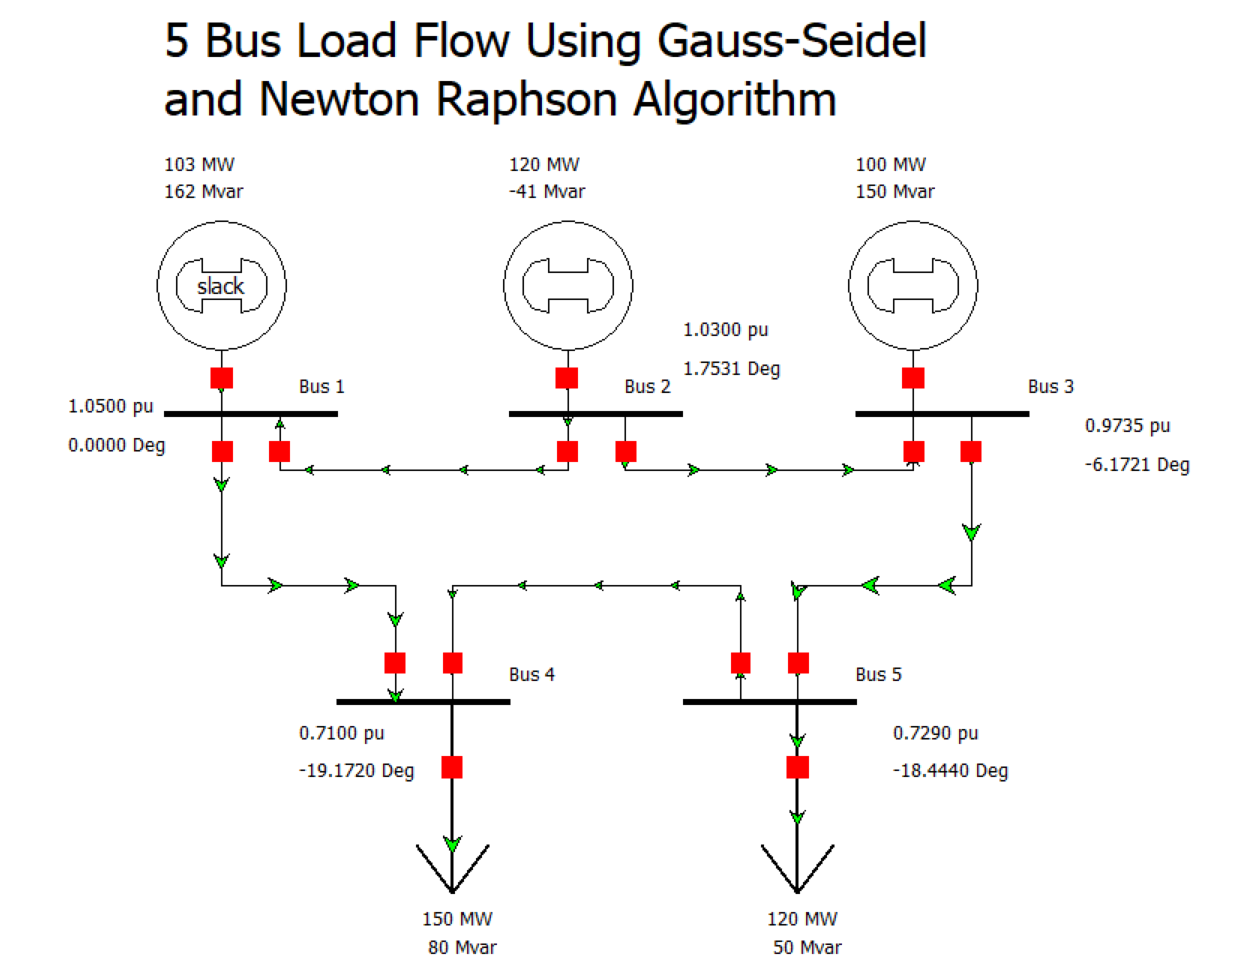

**2. Comparison and Conclusion**

Comparing the PowerWorld data to the MATLAB output shows an exact match in the voltage profile and power flow results. Specifically, both environments confirm that **Bus 3 hits its reactive power limit (**$Q_{\max } =1\ldotp 5\;\mathrm{pu}$**)**, causing the voltage to drop below the initial 1.02 pu setpoint to approximately 0.974 pu. This validates the switching logic implemented in the MATLAB code.